# Effect of Gravity on Pressure

[⇦ Overview](matlab:open('./Overview.m'))

Fluids are continuous material composed of a very large number of particles that do not display a fixed shape. Liquids and gases both display this characteristic with one major difference. Gases tends to occupy all of the volume that is available to them, while liquid tends to occupy a fixed volume. 

How can we study the statics and dynamics of such complex system? What kinf of forces are in action?

Fluid mechanics is the study of fluid at rest (statics) and fluid in motion (dynamics), their characteristics and the forces in action in those systems.

## **What to remember from statics?**

## Effect of pressure on a finite element

[Add the nice picture of Castell]

Catalonian's castell or castel in English, is a human traditional sport from Catalonia that consist in the formation of human tower. 

W = [60 55 75 80 95 100];
F =  9.807*W;
f = cumsum(F);
bar(f)

## **From Castell to Fluid**

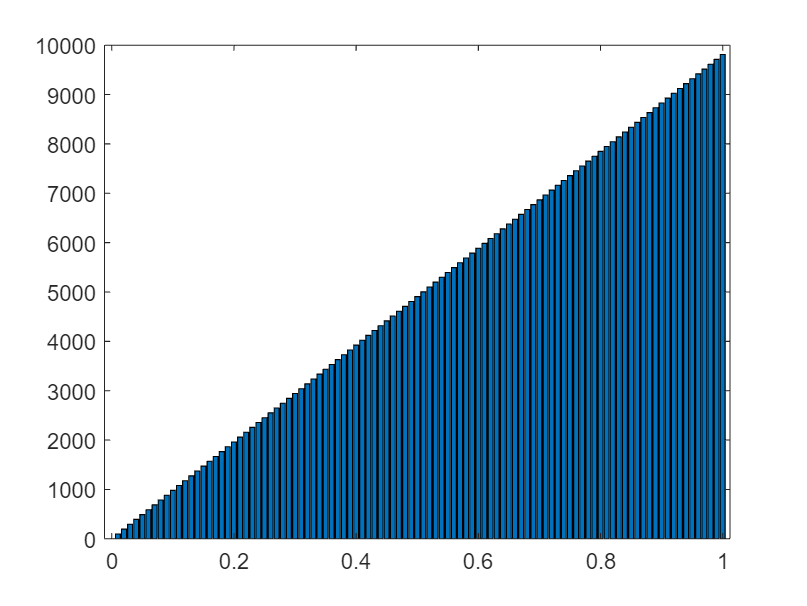

H = 1;
N = 100;
DZ = H / N;
L = 5;
S = L^2;
z = linspace(0,1,N+1);
Rho = 1000;
P = DZ*Rho*9.81*ones(size(z)); P(1) = 0.0;
P = cumsum(P);
bar(z,P)

## Manometer

## Barometer

## Buoyancy 

Draw a cube

syms P(z) z0 P0 g w rho
P(z) = P0 - rho*g*(z-z0)

$$P(z) = P_{0}-g\,\rho \,\left(z-z_{0}\right)$$

Ftop = [0; -P(w)*w^2];
Fbot = [0; +P(0)*w^2];
Fleft = [  w^2*int( P(z), z, 0,w ); 0];
Fright = [-w^2*int( P(z), z, 0,w ); 0];

Ftot = Ftop + Fbot + Fleft + Fright

$$Ftot = \left(\begin{array}{c} 0\\ w^{2}\,\left(P_{0}+g\,\rho \,z_{0}\right)-w^{2}\,\left(P_{0}-g\,\rho \,\left(w-z_{0}\right)\right) \end{array}\right)$$

Ftot = simplify(Ftot)

$$Ftot = \left(\begin{array}{c} 0\\ g\,\rho \,w^{3} \end{array}\right)$$

## Center of pressure and center of gravity

## Stabilty of floating vessel

## Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

[⇦ Return to the navigation page](matlab: OpenOverview)